## Open Methods: Fixed Point Iteration

In this livescript, you will learn how 

- The fixed point iteration method finds a root

- To write a piece of code that implements the method

We'll be considering the problem 


$$f(x)=ax^{2}+(1-a)x=0$$


*Equation 1.*

(a)     Determine the roots of Eq. (1) analytically.

The idea behind fixed point iteration is to recast the the root finding problem


$$f(x)=0$$


into the form 


$$x=g(x)$$


(b)     Show that Eq. (1) can be rearranged into the form $x=g(x)$ where $g(x)=ax(1-x)$.

This suggests that an iterative formula we can use is


$$x_{i+1}=g(x_{i})=ax_{i}(1-x_{i})$$


*Equation 2.*

Looking at Eq. (2), if we keep iterating, the method will converge when when $x_{i+1}=x_{i}=\bar{x}$ which is called a **fixed point** (hence the name of the method). Therefore, we hope that the fixed points of Eq. (2) are also the roots of $f$.

(c)     For $a=2$,  the roots of the equation are $x=0.5$ and $x=0$.  Plot the equations $y=x$ and $y=g(x)$ from (b).  If you have plotted it correctly, you should be able to see the fixed points at $x=0$ and $x=0.5$.

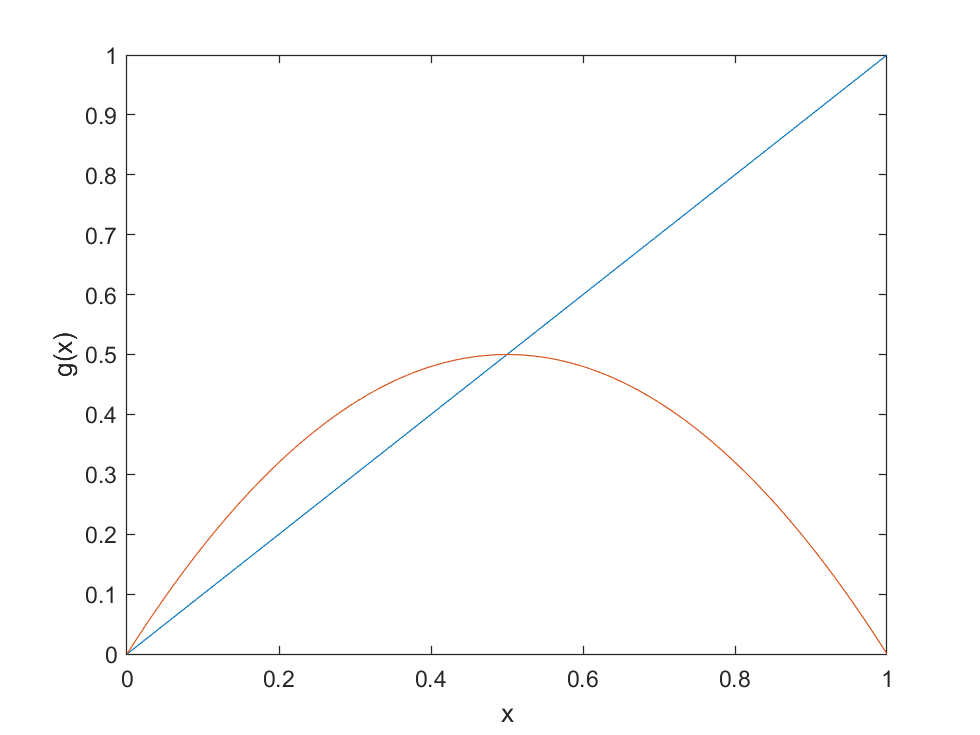

x = linspace(0,1,100);
g = 2*x.*(1-x);
plot(x,x);
hold on
plot(x,g);
xlabel('x');
ylabel('g(x)');
hold off

(d)     Plot Eq. (1) as well, and convince yourselves that the roots of $f$ are the same as the fixed points of $g$.

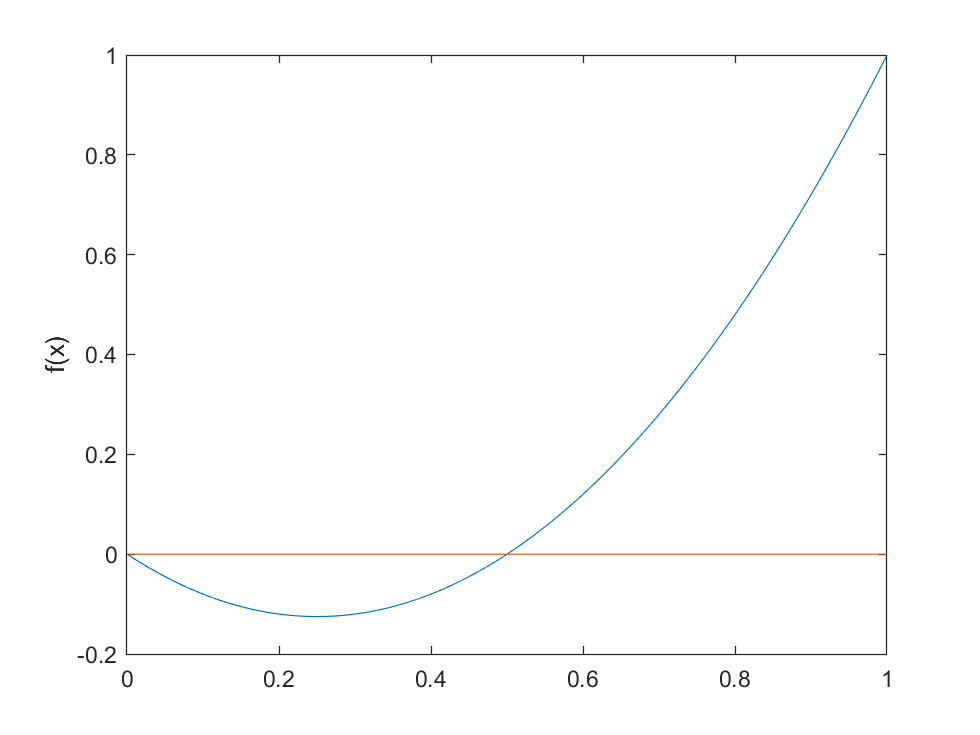

x = linspace(0,1,100);
f=2*x.^2-x;
z=zeros(1,100); %horizontal line at y=0 so that it is clear where the root is. 
plot(x,f,x,z)
ylabel('f(x)')

In fact, this plot of $y=x$ and $y=g(x)$ provides us with a vast amount of information on the iterative process. 

So, let's slightly modify the fixed point algorithm to take advantage of this.

- Let $i=0$ and select an initial point $x=x_{0}$ and $y=x_{0}$.

- The first step involves finding $g(x_{i})$, so we move vertically until we hit the line $y=g(x)$, i.e. to the point $(x_{i},g(x_{i}))$.

- Set $x_{1}=g(x_{0})=y$, or equivalently move horizontally until we hit the line $y=x$, i.e. to the point $(g(x_{i}),g(x_{i}))$.

- Let $i=i+1$.

- Go back to step 2.

Plotting $y=x$ and $y=g(x)$ gives

figure(1)
x = linspace(0,1,100);
g = 2*x.*(1-x);
plot(x,x);
hold on
plot(x,g);
xlabel('x');
ylabel('g(x)');
hold off

**Step 1:** Choosing the initial guess $x=0.8$, we therefore start at the point $(0.8,0.8)$. 

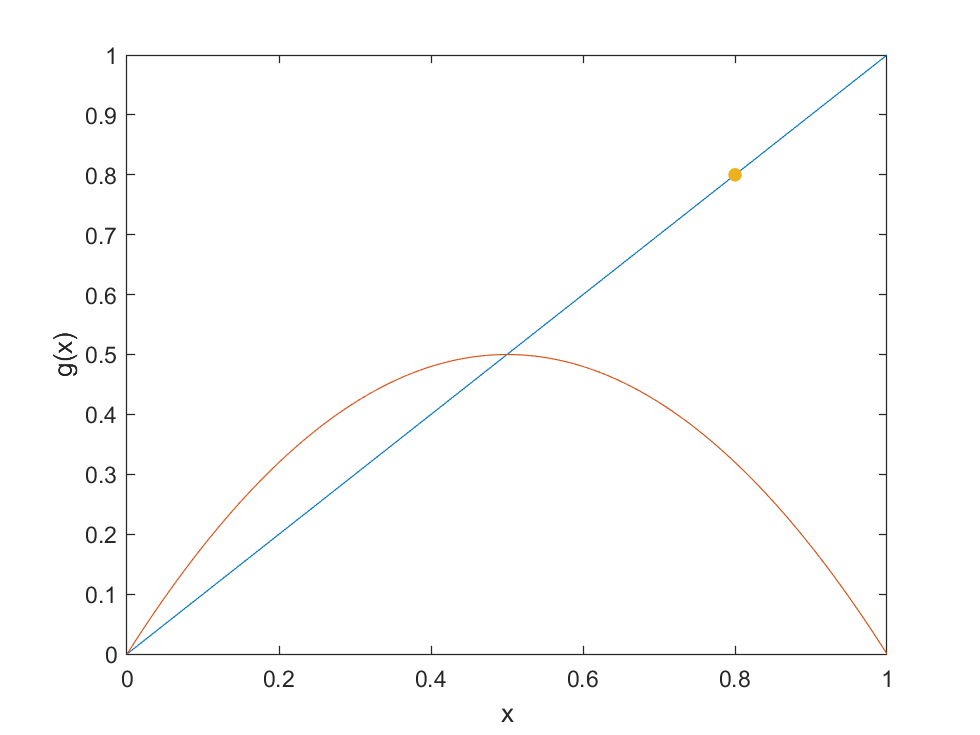

figure(2)
plot(x,x);
hold on
plot(x,g);
xlabel('x');
ylabel('g(x)');
plot([0.8],[0.8],'.-','MarkerSize',20)

**Step 2:** Evaluating $g(x_{0})=2x_{0}(1-x_{0})=0.32$, so we move downwards to the point $(0.8,0.32)$.

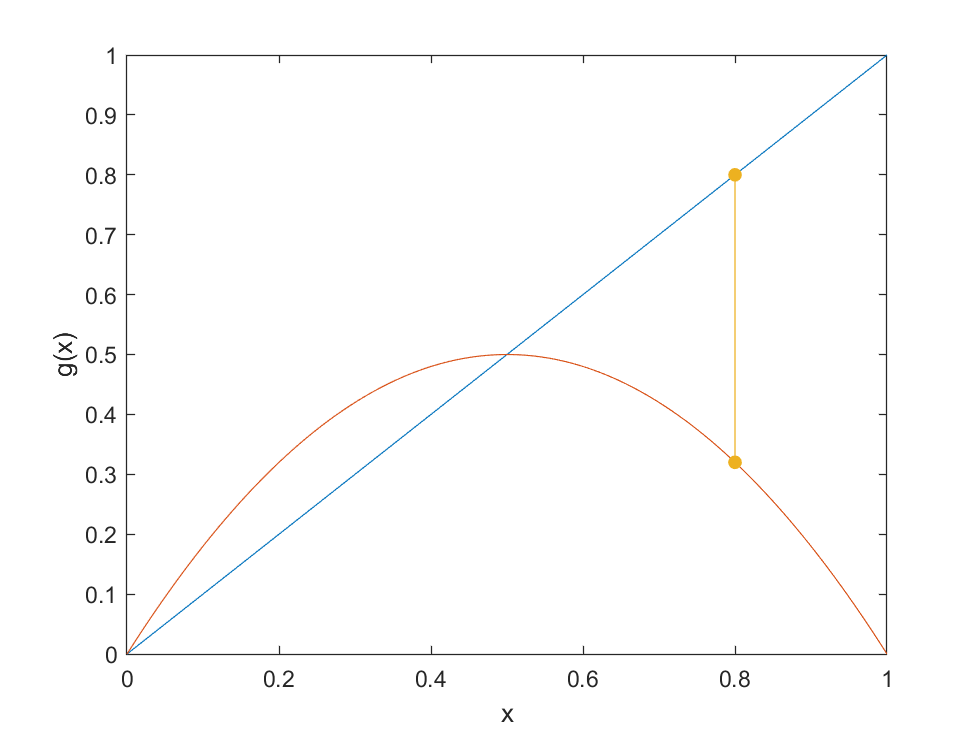

figure(3)
plot(x,x);
hold on
plot(x,g);
xlabel('x');
ylabel('g(x)');
plot([0.8, 0.8],[0.8, 0.32],'.-','MarkerSize',20)

**Step 3:** We now set $x_{1}=g(x_{0})=0.32$, moving horizontally to $(0.32,0.32)$.

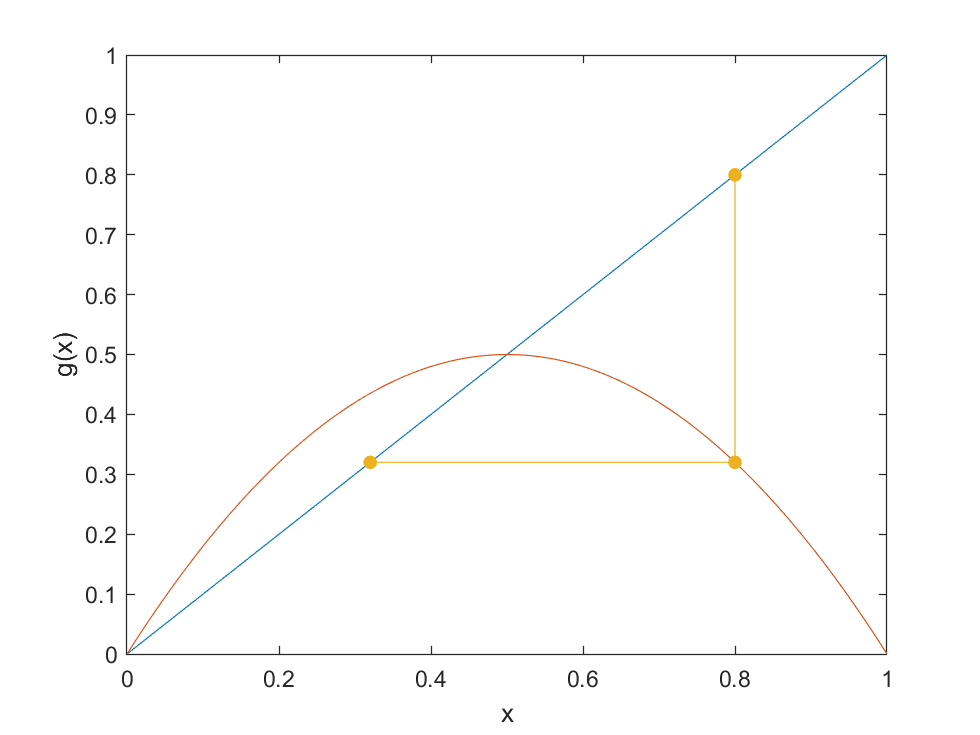

figure(4)
plot(x,x);
hold on
plot(x,g);
xlabel('x');
ylabel('g(x)');
plot([0.8, 0.8, 0.32],[0.8, 0.32, 0.32],'.-','MarkerSize',20)

**Step 4 & 5:** We now set $i=2$ and repeat the process.

To get an idea of what this looks like, the following function $\texttt{fixed\_point\_iteration\_example}$ repeats the process until it converges.

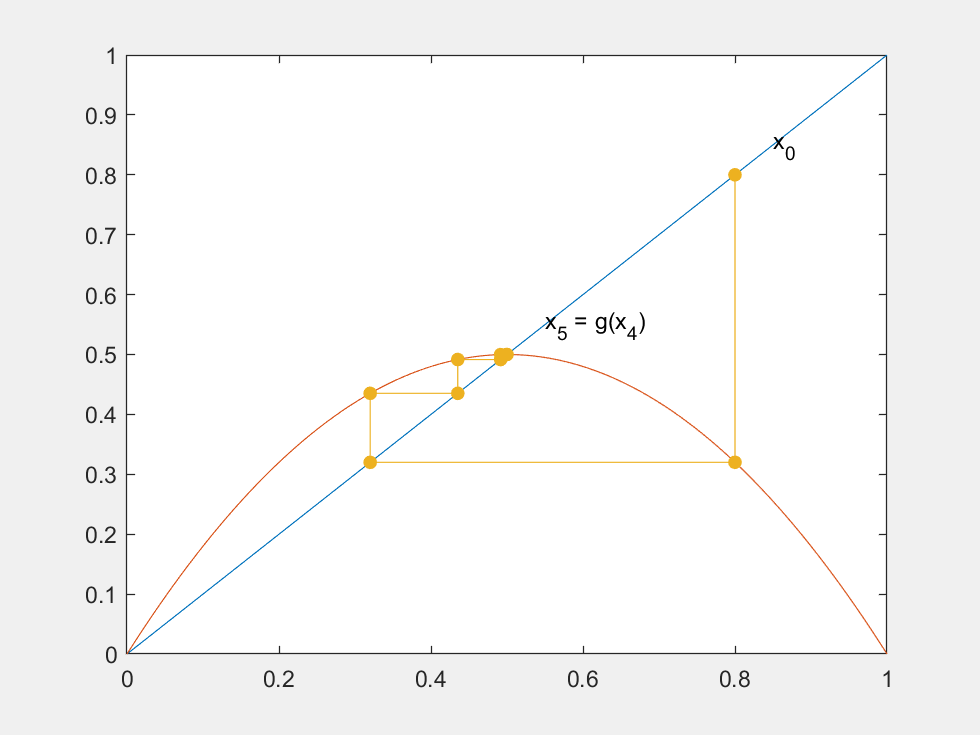

fixed_point_iteration_example()

NOTE: You don't have to understand how fixed_point_iteration_example() works right now.

This is what's called a **cobweb plot**, and you should be able to see how it may be used in determining the long term behaviour of the iterative process (i.e. whether it converges or not and to what value). 

A less convoluted piece of code that implements fixed point iteration is therefore

(e)     Run $\texttt{fixed\_point\_iteration\_solver}$ below and make sure you understand each line.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% fixed_point_iteration_solver %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

a = 2;
g = @(x) a*x.*(1-x);           

x = 0.6;                          % Initial Condition
tol = 10^-6;                      % Tolerance of 10e-6
max_iter = 100;                   % This line is prevents the method from iterating in the case it diverges
i = 1;
while abs(x-g(x))>tol && i<max_iter
    
    x = g(x);
    i = i+1;
    
    fprintf('%11.10f\n',x)

end

0.4800000000
0.4992000000
0.4999987200
0.5000000000


What value of x does the loop converge to? Can you get the algorithm to converge to the root at $x=0$?  If not, why not (see (h) below for a hint)?

(f)  Now let's see what happens when we change the value of a to  $a=3.2$  Plot Eq. (1) and (2)

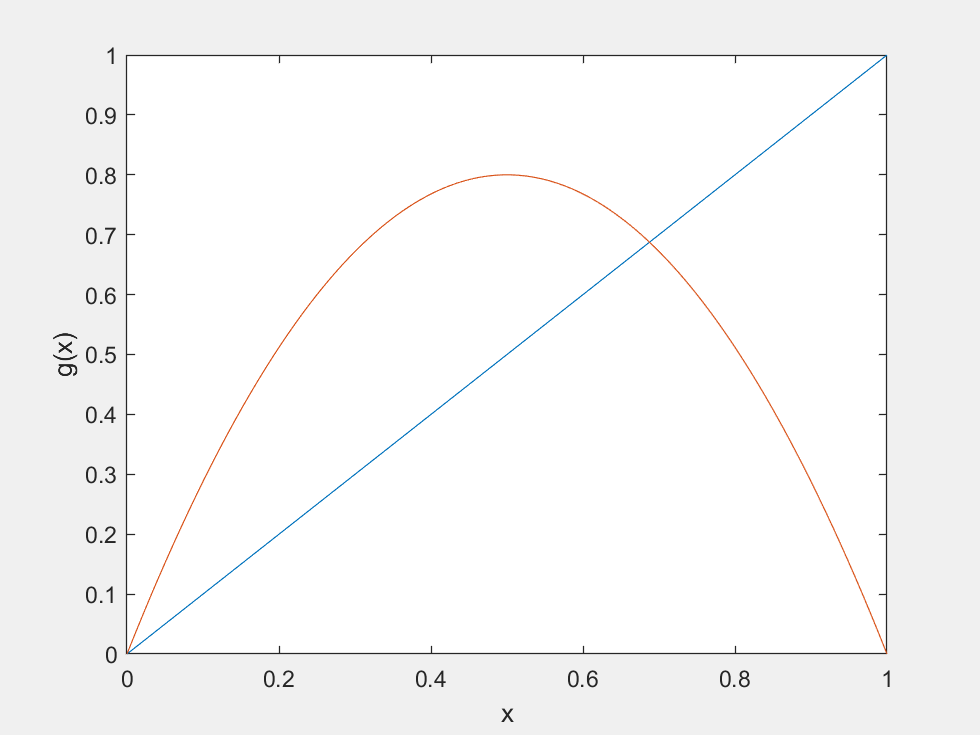

figure(5)
a = 3.2;


x = linspace(0,1,100);


g = a*x.*(1-x); 


plot(x,x,x,g)
xlabel('x')
ylabel('g(x)')

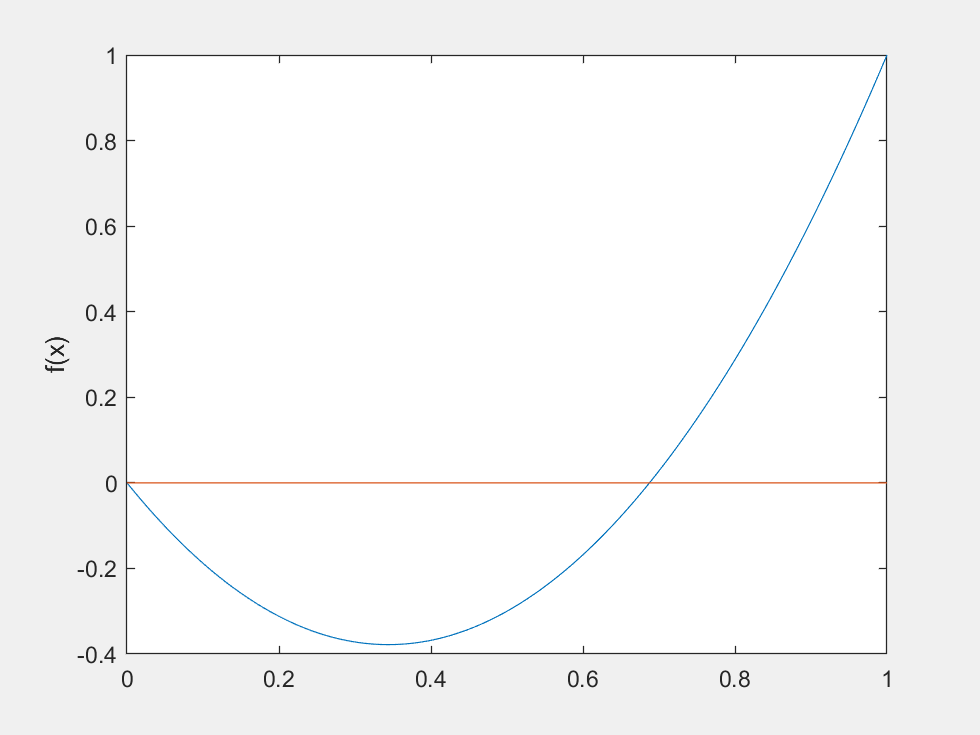

f= a*x.^2+(1-a)*x;
z=zeros(1,100); %horizontal line at y=0 so that it is clear where the root is. 
plot(x,f,x,z)
ylabel('f(x)')

It is clear from the figures above that there is now a root of $f(x)$ between $0.6 \le x \le 0.8$. 

(g)     Modify $\texttt{fixed\_point\_iteration\_solver}$ to solve Eq. (1) with $a=3.2$. Start at the initial condition $x_{0}=0.8$. What happens and why?

In fact, this instability in the algorithm occurs $\forall a>3$. So when we choose to use fixed point iteration, we have to be very careful in choosing $g(x)$. 

A way to determine whether the iteration process will converge to the root is to compute the linear stability of the fixed point $\bar{x}$. What this means is that very close to the fixed point, the function is approximately linear (recall the definition of a derivative). So if we perform the iterative process graphically, we can see whether or not the process converges to/diverges from the fixed point $\bar{x}=x_{r}$.

In fact, it can be shown that the condition for linear stability is $\lambda=|g'(\bar{x})|<1 $.

(h)    The code below shows you the process of iteration for the linearised function $g(x)=\lambda x$ from an initial guess $x_{0}=0.5$. Try varying $\lambda$ and convince yourselves that the condition for linear stability holds for the fixed point at $\bar{x}=x_{r}=0$.

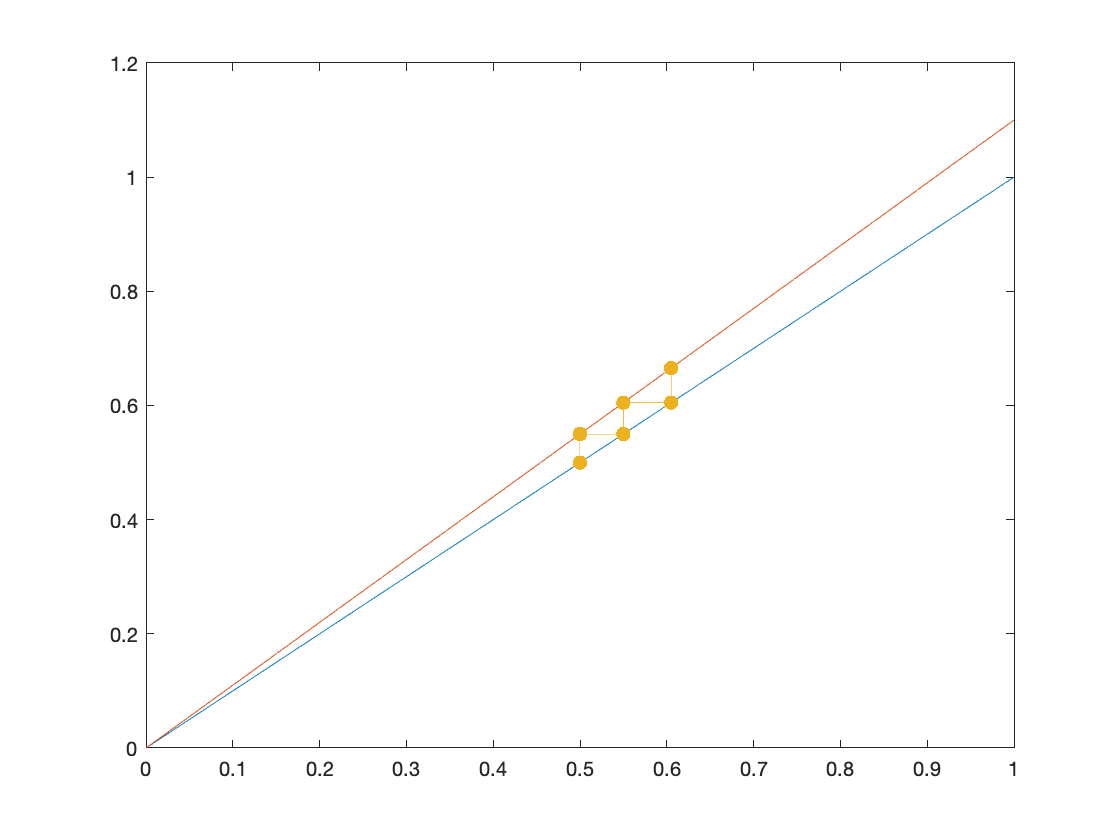

figure()
lambda = 1.1;
f = @(x) lambda.*x;
x = linspace(0,1);
x0 = 0.5;
plot(x,x);
hold on
plot(x,f(x));
plot([x0, x0, f(x0), f(x0),f(f(x0)),f(f(x0))],[x0, f(x0), f(x0), f(f(x0)),f(f(x0)),f(f(f(x0)))],'.-','MarkerSize',20)

(i)    Looking at Eq. (1) again, for $a=3.2$, one of the roots is located at 0.6875.  What is the gradient of $g(x=0.6875)$? Will the method converge to this root?